clear
clc
close all

a = arduino("COM3", "Mega2560")

a =   arduino with properties:

                  Port: 'COM3'
                 Board: 'Mega2560'
         AvailablePins: {'D2-D53', 'A0-A15'}
  AvailableDigitalPins: {'D2-D53', 'A0-A15'}
      AvailablePWMPins: {'D2-D13', 'D44-D46'}
   AvailableAnalogPins: {'A0-A15'}
    AvailableI2CBusIDs: [0]
AvailableSerialPortIDs: [1, 2, 3]
             Libraries: {'APDS9960', 'Adafruit/MotorShieldV2', 'CAN', 'I2C', 'RotaryEncoder', 'SPI', 'Serial', 'Servo', 'ShiftRegister', 'Ultrasonic'}
Show all properties


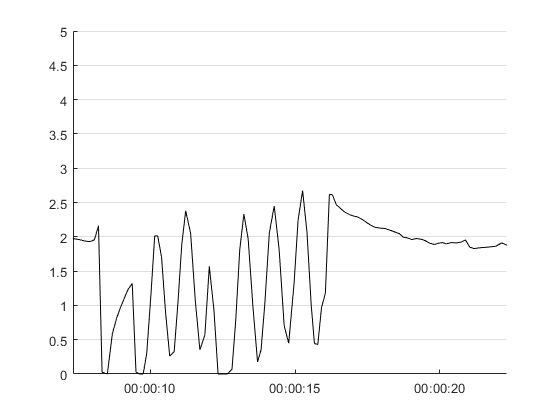

Unable to receive data from the target hardware.
 For MATLAB, reconnect the target hardware, clear the hardware objects and try again.
 For Simulink, reconnect the target hardware and start simulation again.

configurePin(a, "A0", "AnalogInput")



h = animatedline;
ax = gca;
ax.YGrid = 'on';
ax.YLim = [0 5];

stop = false;
startTime = datetime('now');
while ~stop
    
    v = readVoltage(a, 'A0');
    t = datetime('now') - startTime;
    addpoints(h,datenum(t),v)
    ax.XLim = datenum([t-seconds(15) t]);
    datetick('x', 'keeplimits')
    drawnow

end